# Radar Signal Processing Verification

This script has been written to confirm that the signal processing component of a radar is working as anticipated

## Initialize the simulator

clear;
simulator = Simulator_revB();
 file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highvres.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_lowBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_sensing_system.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/X310_params_100MHzBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/realistic_params.json";
simulator.load_params_from_JSON(file_path);


%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.20 MHz/us
	 Idle Time: 			 1.95 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.49 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 1.54 MSps
	 Ramp End Time: 		 48.05 us
	 Chirp Tx Bandwidth: 		 57.66 MHz
	 Chirp Sampling Bandwidth: 	 49.87 MHz
	 ADC Sampling Period: 		 41.56 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 64
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.20 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 192.37 m
	 Range Resolution 		 3.01 m
	 Max Velocity 			 19.47 m/s
	 Velocity Resolution 		 0.61 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 58.52 MHz
	 Downsampling factor 		 38
	 Sweep time 			 48.05 us
	 Samples per chirp 		 2926.00 


## Initialize the Target

simulator.load_target_realistic();

## Initialize the Victim and Simulation Parameters

%specify the number of frames and chirps to compute
frames_to_compute = 100;

%specify whether or not to record a move of the range-doppler plot
record_movie = true;
simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute,record_movie);

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

## Initialize the Attacker

%initialize the attacker parameters
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(1,simulator.Victim,frames_to_compute);

%initialize the attacker
simulator.Attacker.Subsystem_attacking.set_attacker_parameters(75,5,"target");

## Run the Simulation

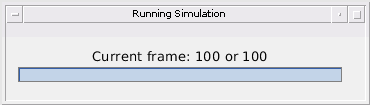

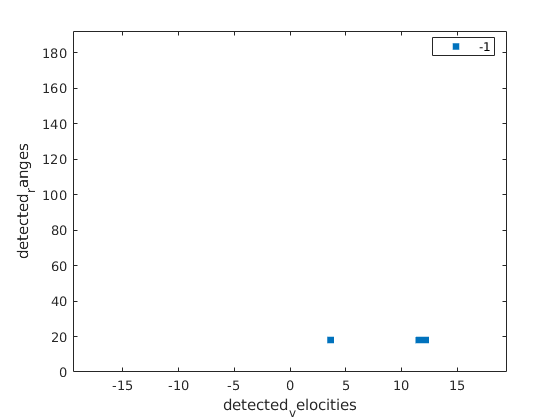

%run the simulation (without an attacker for now)
simulator.run_simulation_with_attack(frames_to_compute);

## Results

%get the estimated ranges and velocities
simulator.Victim.Radar_Signal_Processor.range_estimates

ans =    51.3065       NaN       NaN       NaN       NaN
   52.0214       NaN       NaN       NaN       NaN
   52.7522       NaN       NaN       NaN       NaN
   53.1781       NaN       NaN       NaN       NaN
   53.5340       NaN       NaN       NaN       NaN
   53.9766   70.9752       NaN       NaN       NaN
   17.3940   54.2318       NaN       NaN       NaN
   16.5315   49.2685       NaN       NaN       NaN
   19.5373   50.1113       NaN       NaN       NaN
   16.5315   50.4968       NaN       NaN       NaN


simulator.Victim.Radar_Signal_Processor.velocity_estimates

ans =    12.0284       NaN       NaN       NaN       NaN
   12.0289       NaN       NaN       NaN       NaN
   12.0317       NaN       NaN       NaN       NaN
   12.0285       NaN       NaN       NaN       NaN
   12.0313       NaN       NaN       NaN       NaN
   12.0303    3.5301       NaN       NaN       NaN
    3.5294   12.0344       NaN       NaN       NaN
    3.5293   12.0308       NaN       NaN       NaN
    3.5296   12.0306       NaN       NaN       NaN
    3.5295   12.0335       NaN       NaN       NaN


%play the movie for the range doppler
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_range_doppler_movie();
end

%play the movie for the clusters
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_clustering_movie()
end